format shortg
clear all

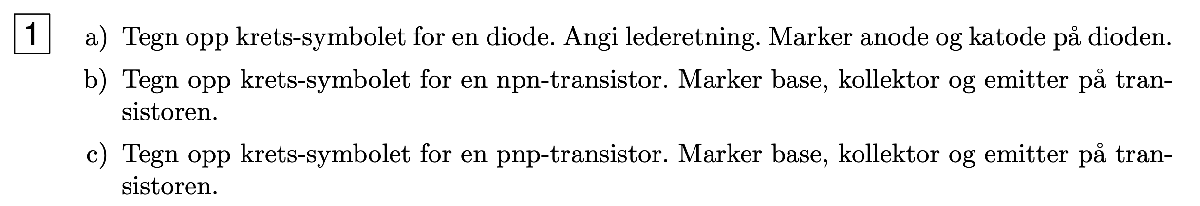

(a)

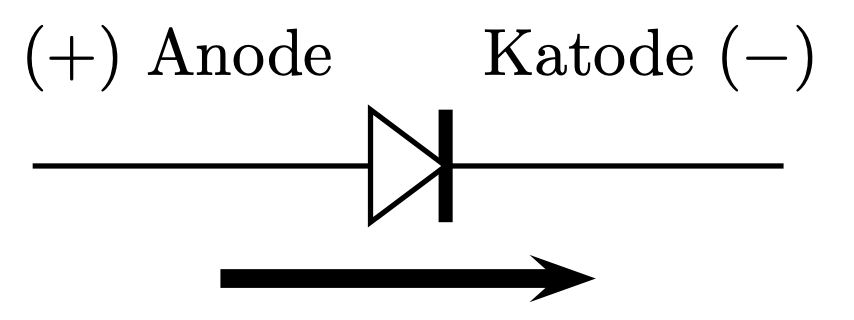

(b)

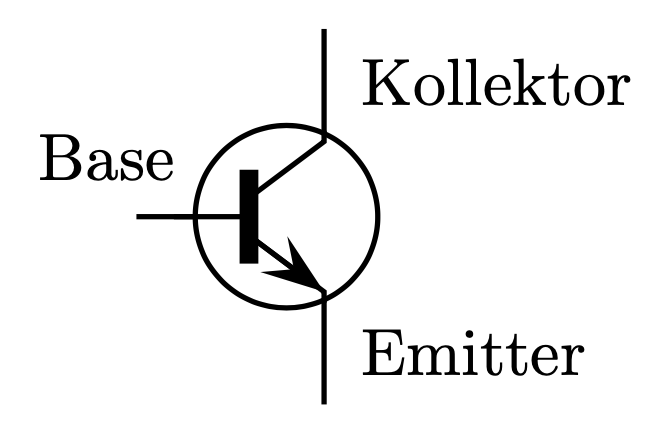NPN (Nålen Peker Ned)

NPN transistor:


$$\begin{array}{l}
\beta =h\;f\;e\\
I_{\mathrm{kollektor}} =\beta *I_{\mathrm{base}} \\
I_{\mathrm{emitter}} =I_{\mathrm{kollektor}} +I_{\mathrm{base}} =I_{\mathrm{base}} \left(\beta +1\right)
\end{array}$$


I_base = 50 * 10^-6;
beta = 200;
I_kollektor = I_base*beta

I_kollektor =          0.01


I_emitter = I_base + I_kollektor

I_emittor =       0.01005


I_emitter = I_base*(beta + 1)

I_emittor =       0.01005


dersom $h\;f\;e=\beta \;$er stor, vil $I_{\mathrm{emittor}} \approx I_{\mathrm{kollektor}}$


$$\begin{array}{l}
V_{\mathrm{kollektor}-\mathrm{emitter}} =V_{\mathrm{kollektor}} -V_{\mathrm{emitter}} \\
V_{\mathrm{base}-\mathrm{emittor}} =V_{\mathrm{base}} -V_{\mathrm{emitter}} \;\left(\mathrm{vil}\;\mathrm{vanligvis}\;\mathrm{være}\;\mathrm{rundt}\;0\ldotp 6V-0\ldotp 7V,\mathrm{og}\;\mathrm{er}\;\mathrm{relativt}\;\mathrm{konstant}\right)\\
V_{\mathrm{kollektor}-\mathrm{base}} =V_{\mathrm{kollektor}} -V_{\mathrm{base}} 
\end{array}$$


Det vil ikke gå strøm fra gjennom kollektor-emittor dersom spenningen over $V_{\mathrm{base}-\mathrm{emitter}} \;\mathrm{er}\;\mathrm{mindre}\;\mathrm{enn}\;0\ldotp 6\;V-0\ldotp 7V$

(c)

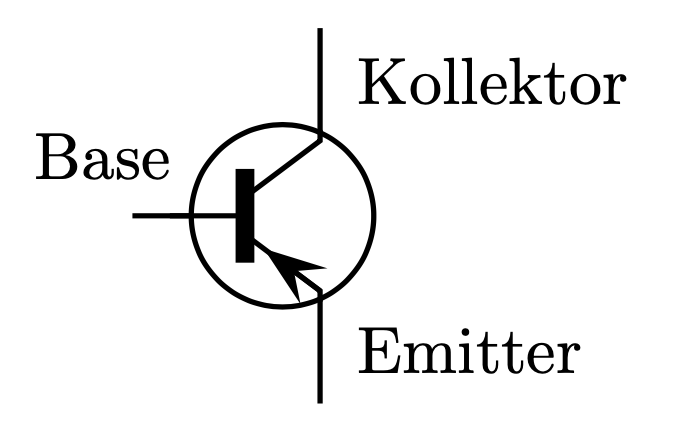PNP

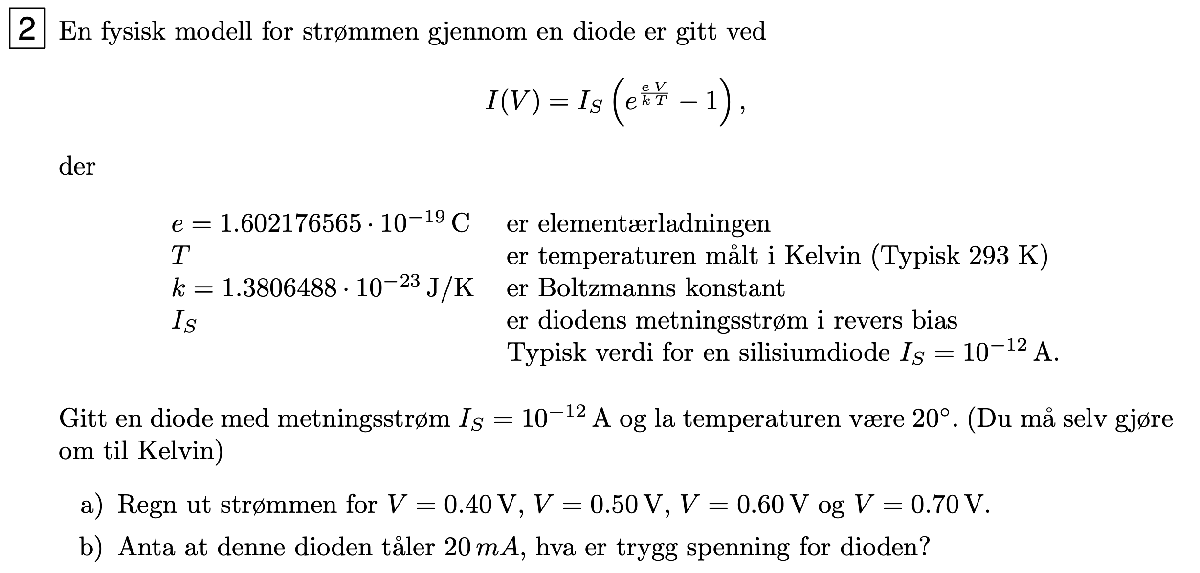

I_S = 10^-12; % Ampere
T = 20 + 273.15; % Kelvin
k = 1.3806488 * 10^-23; % J/K

I = @(V) I_S * (exp((e*V)/(k*T)) - 1);

(a)

signif(I(0.40), 3)

ans =      7.53e-06


signif(I(0.50), 3)

ans =      0.000394


signif(I(0.5992), 3)

ans =          0.02


signif(I(0.60), 3)

ans =        0.0207


signif(I(0.70), 3)

ans =          1.08


(b)

Fra resultatene i (a) kan ikke spenningen være mer enn 0.60V. Nøyaktiv verdi: $0\ldotp 5992\;\mathrm{Volt}$

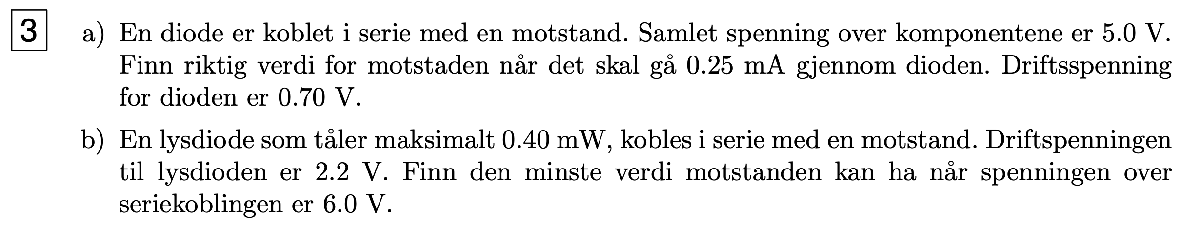

(a)

e_b = 5.0; % V
I = 0.25 * 10^-3; % A
driftspenning = 0.70; % V
R_kollektor = ohms_lov((e_b - driftspenning), 0, I)

R =        17200


(b)

maks_effekt = 0.40 * 10^-3; % Watt
driftspenning = 2.2; % V
e_b = 6.0; % V
I = ElektriskEffekt(maks_effekt, driftspenning, 0, 0)

I =    0.00018182


R_kollektor = ohms_lov(e_b-driftspenning, 0, I)

R =        20900


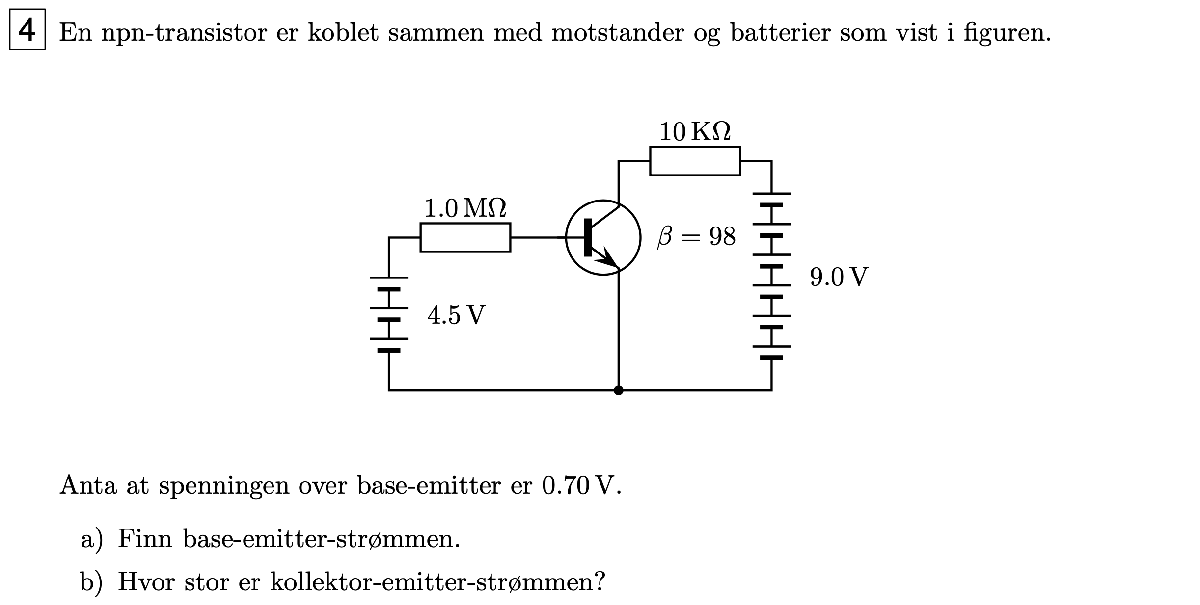

e_b1 = 4.5; % Volt
R_base = 1.0 * 10^6; % Ohm
R_kollektor = 10 * 10^3; % Ohm
e_b2 = 9.0; % Volt
beta = 98;
V_base_emitter = 0.70; % V

(a)

base-emitter strømmen vil kun være strømmen gjennom den lille kretsen til venstre, bruker derfor ohms lov til å finne strømmen gjennom $R_{\mathrm{base}}$

I_base = ohms_lov((e_b1 - V_base_emitter), R_base, 0)

I_base =       3.8e-06


(b)


$$I_{\mathrm{kollektor}} =\beta *I_{\mathrm{base}}$$


I_kollektor = beta * I_base;
signif(I_kollektor, 2)

ans =       0.00037


(c)


$$V_{\mathrm{kollektor}-\mathrm{emitter}} =V_{\mathrm{kollektor}} -V_{\mathrm{emitter}}$$


V_kollektor = ohms_lov(0, R_kollektor, I_kollektor);
V_emitter = 0;
V_kollektor_emitter = V_kollektor - V_emitter;
signif(V_kollektor_emitter, 2)

ans =           3.7


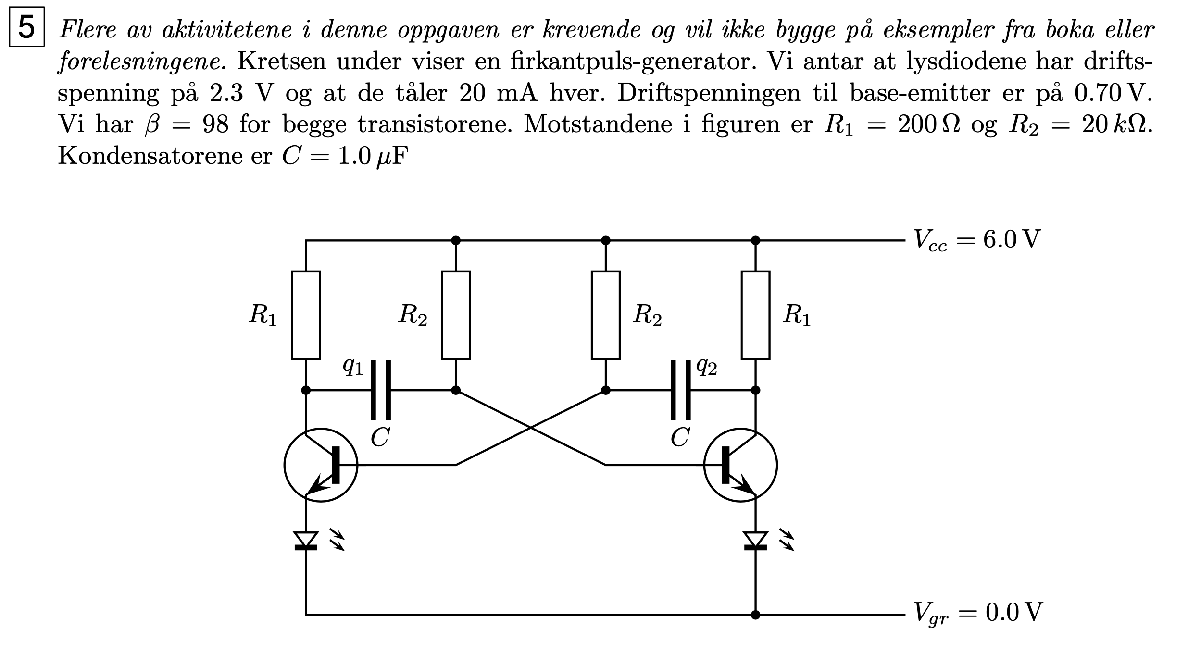

driftspenning_diode = 2.3; % V
maks_strom_diode = 20 * 10^-3; % A
V_base_emitter = 0.70; % V
beta = 98;
R1 = 200; % Ohm
R2 = 20 * 10^3; % Ohm
C = 1.0 * 10^-6; % F
V_cc = 6.0; % V

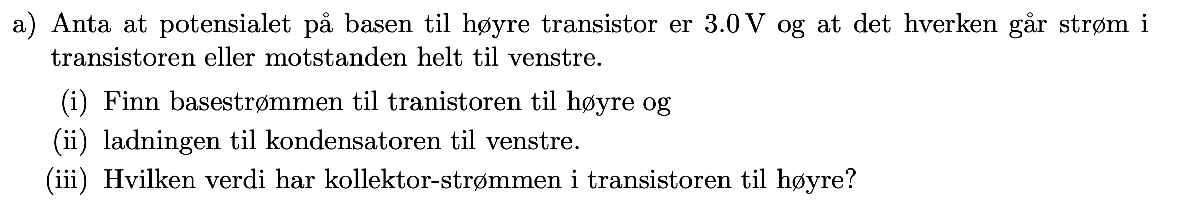

V_base_hoyre = 3.0;

(i) 

Strømmen i basen til transistoren vil være lik strømmen gjennom motstand $R_2$ nå de ikke går strøm gjennommotstanden til venstre eller transistoren til venstre.

I_base_hoyre = ohms_lov(V_base_hoyre, R2, 0)

I_base_hoyre =       0.00015


(ii)

potensialet til høyre til kondensatoren til venstre vil være lik potensialet ved basen til høyre transistor. siden det ikke går strøm gjennom motsand $R_1$ vil potensialet på andre siden være 0

V_C_venstre = V_base_hoyre;


$$C_{\mathrm{venstre}} =\frac{\mathrm{q1}}{U_{\mathrm{Cvenstre}} }$$


q1 = C * V_C_venstre

q1 =         3e-06


(iii)


$$I_{\mathrm{kollektor}} =\beta *I_{\mathrm{base}}$$


I_kollektor_hoyre = beta * I_base_hoyre

I_kollektor_hoyre =        0.0147


q2 = 3.0 * 10^-6; % C


$$C_{\mathrm{hoyre}} =\frac{\mathrm{q2}}{U_{\mathrm{Choyre}} }$$


V_C_venstre = q2/C

V_C_venstre =      3


Finner potensialfallet over motstand $R_1$til høyre:

V_R1_hoyre = ohms_lov(0, R1, I_kollektor_hoyre)

V_R1_hoyre =          2.94


Potensiale ved basen til venstre blir da:

V_base_venstre = V_cc - V_R1_hoyre - V_C_venstre

V_base_venstre =          0.06


Nei det vil ikke gå strøm i transistoren til venstre siden potensialet på 0.06 ikke er stort nok til å danne en base-emitter spenning på over 0.7 V, og hvertfall ikke stort nok til å oppnå spenningen for at dioden skal lede strøm i tilleg: $0\ldotp 7V+2\ldotp 3V=3V$, altså trenger vi et potensial ved basen på over 3V før det kan gå strøm.